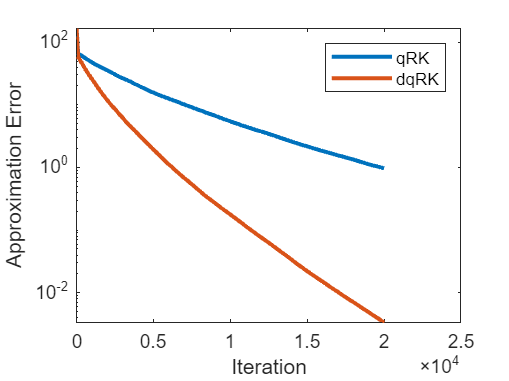

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


% Add path to functions
addpath('Functions\')

% Store path to custom matrices
filepath = "Matrix\";

%   Algorithm parameters
MAX_ITERATIONS  = 20000;
q0              = 3/5;
q1              = 4/5;
beta            = 0.05;

% Matrix Setup
mat_type            = "unifrand";
mat_name            = "ash958";
extension           = ".mat";
addgaussianfactor   = 0; % 1/100 for ash958
[m,n,A,x,b]         = SystemSetup(2500,500,mat_type,beta,filepath+mat_name+extension,addgaussianfactor);

% Graph Parameters 
% xpoints and graphstep serve to only display every graphstep-th point of the graph
graphstep       = 100;
xpoints         = 1:graphstep:MAX_ITERATIONS+1;


%------------------------------------------------------

% Initialization 
xk      = zeros(n,1);
dxk     = zeros(n,1);

% Data collection values
err     = zeros(MAX_ITERATIONS+1, 1);
derr    = zeros(MAX_ITERATIONS+1, 1);

err(1)      = norm(x - xk)^2;
derr(1)     = norm(x - dxk)^2;

% Run qRK and dqRK for MAX_ITERATIONS iterations
for iter = 1:MAX_ITERATIONS

    % Run a step of each algorithm
    xk     = qRKalgstep(A,xk,b,q1);
    dxk    = dqRKalgstep(A,dxk,b,q0,q1);
       
    % Data collection
    err(iter + 1)       = norm(x - xk)^2;
    derr(iter + 1)      = norm(x - dxk)^2;

end

% Plot error graphs
errgraph = semilogy(xpoints,err(xpoints),'DisplayName','qRK','LineWidth', 2);
hold on
semilogy(xpoints,derr(xpoints),'DisplayName','dqRK', 'LineWidth', 2);

xlabel("Iteration")
ylabel("Approximation Error")
legend
hold off

% Save tikz plot
if mat_type ~= "custom"
    mat_name = mat_type;
end
if addgaussianfactor ~= 0
    mat_name = mat_name + "_plus_gaussian"
end
filename = "Figs\qRK_dqRK_" + mat_name;
saveas(errgraph, filename, 'fig');
filename = convertStringsToChars(filename+".tex");
matlab2tikz(filename)